%TVB parameter comparisons

pbfs = readtable("Parameter_best_fits.xlsx")

pbfs = 34×9 table
    Subject    Visit     Group     Age    G_bf     D_bf     Ji_bf    Jn_bf    wpJn_bf
    _______    _____    _______    ___    ____    ______    _____    _____    _______

     10003       4      {'ASD'}    65     0.3     0.0001       1     0.125      0.5  
     10020       2      {'ASD'}    60     0.6      0.001     1.2     0.175      0.5  
     10069       2      {'ASD'}    61     0.3     0.0001     1.1     0.175      1.8  
     10077       3      {'ASD'}    72     0.3     0.0001     1.1     0.125        2  
     10090       2      {'ASD'}    66     0.7      0.001     1.5     0.175      0.5  
     10091       3      {'ASD'}    71     0.3     0.0001       1     0.12

ASD_G = pbfs{1:17,'G_bf'};
NT_G = pbfs{18:34,'G_bf'};

ASD_D = pbfs{1:17,'D_bf'};
NT_D = pbfs{18:34,'D_bf'};

ASD_Ji = pbfs{1:17,'Ji_bf'};
NT_Ji = pbfs{18:34,'Ji_bf'};

ASD_Jn = pbfs{1:17,'Jn_bf'};
NT_Jn = pbfs{18:34,'Jn_bf'};

ASD_wpJn = pbfs{1:17,'wpJn_bf'};
NT_wpJn = pbfs{18:34,'wpJn_bf'};

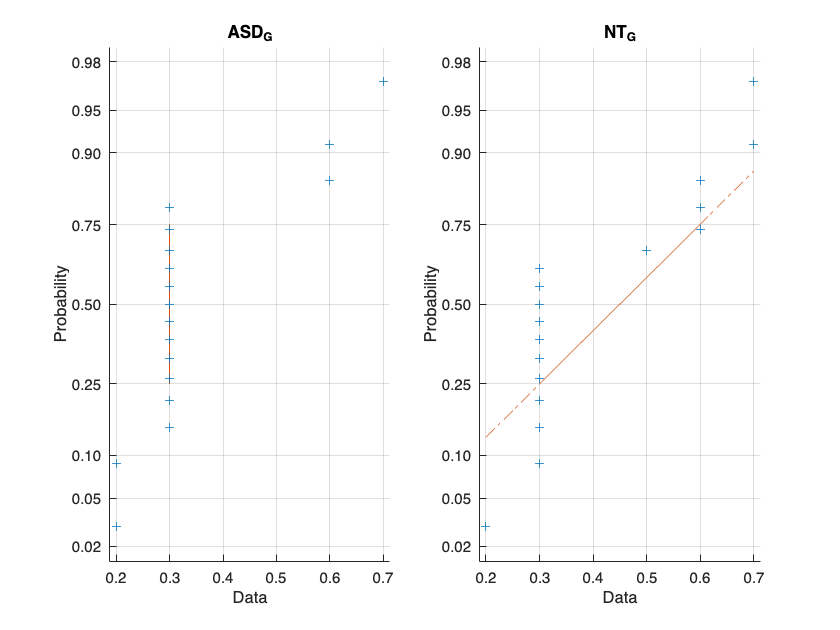

figure;
subplot(1,2,1)
normplot(ASD_G)
title('ASD G')
subplot(1,2,2)
normplot(NT_G)
title('NT G')

G_diff = mwwtest(ASD_G', NT_G');

MANN-WHITNEY-WILCOXON TEST
 
                       Group_1    Group_2
                       _______    _______

    Numerosity             17         17 
    Sum_of_Rank_W         269        326 
    Mean_Rank          15.824     19.176 
    Test_variable_U       173        116 

Sample size is large enough to use the normal distribution approximation
 
    Mean       SD        Z       p_value_one_tail    p_value_two_tails
    _____    ______    ______    ________________    _________________

    144.5    24.723    1.1325         0.1287              0.2574      

 


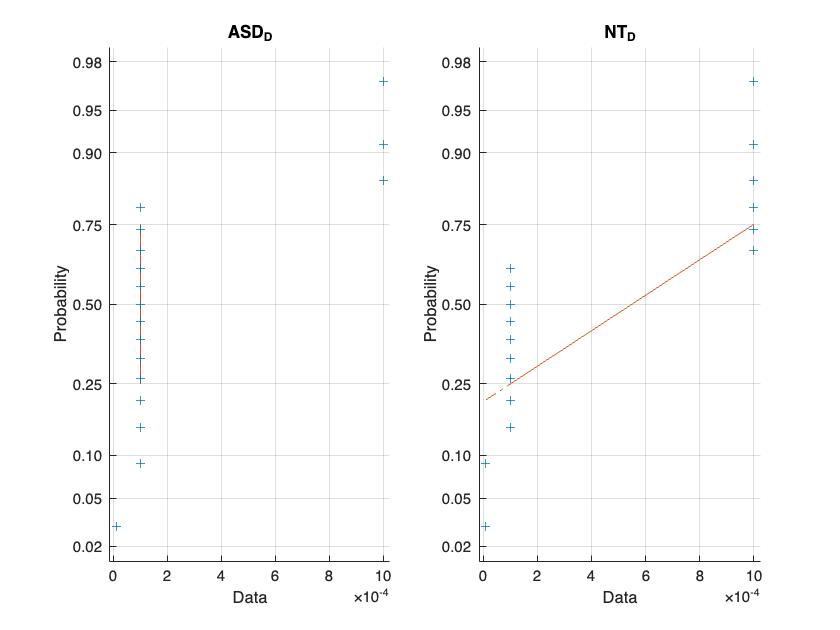

figure;
subplot(1,2,1)
normplot(ASD_D)
title('ASD D')
subplot(1,2,2)
normplot(NT_D)
title('NT D')

D_diff = mwwtest(ASD_D', NT_D');

MANN-WHITNEY-WILCOXON TEST
 
                       Group_1    Group_2
                       _______    _______

    Numerosity             17         17 
    Sum_of_Rank_W       280.5      314.5 
    Mean_Rank            16.5       18.5 
    Test_variable_U     161.5      127.5 

Sample size is large enough to use the normal distribution approximation
 
    Mean       SD         Z       p_value_one_tail    p_value_two_tails
    _____    ______    _______    ________________    _________________

    144.5    24.472    0.67425        0.25008              0.50015     

 


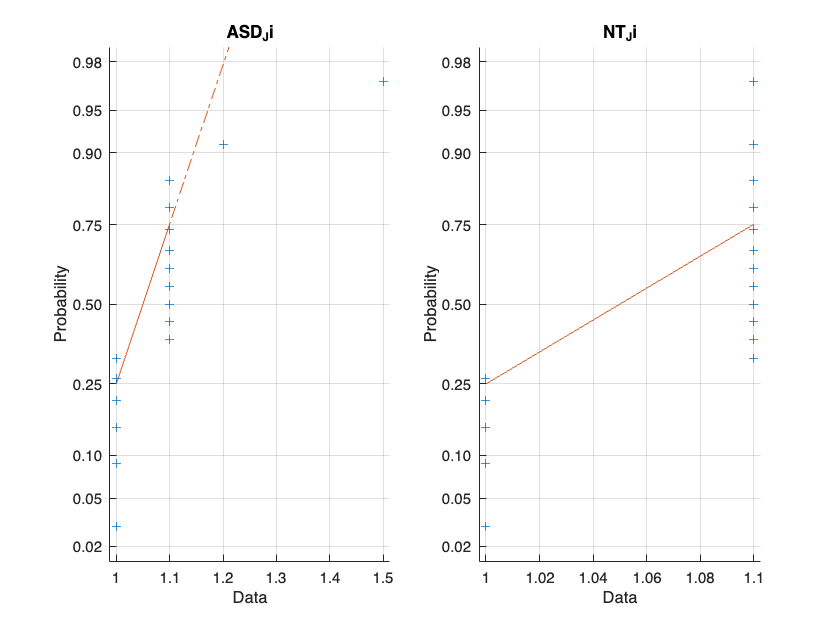

figure;
subplot(1,2,1)
normplot(ASD_Ji)
title('ASD Ji')
subplot(1,2,2)
normplot(NT_Ji)
title('NT Ji')

Ji_diff = mwwtest(ASD_Ji', NT_Ji');

MANN-WHITNEY-WILCOXON TEST
 
                       Group_1    Group_2
                       _______    _______

    Numerosity             17         17 
    Sum_of_Rank_W         301        294 
    Mean_Rank          17.706     17.294 
    Test_variable_U       141        148 

Sample size is large enough to use the normal distribution approximation
 
    Mean       SD         Z       p_value_one_tail    p_value_two_tails
    _____    ______    _______    ________________    _________________

    144.5    24.824    0.12085        0.45191              0.90381     

 


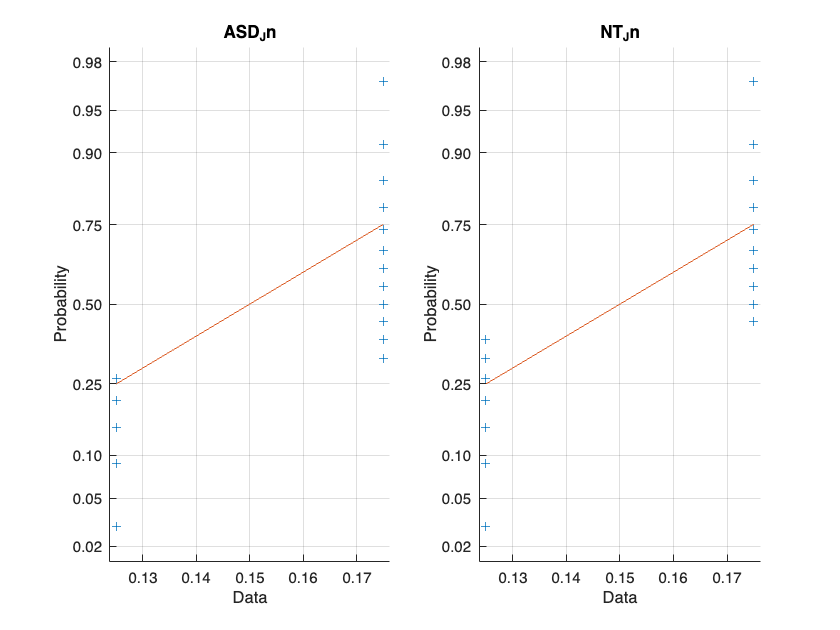

figure;
subplot(1,2,1)
normplot(ASD_Jn)
title('ASD Jn')
subplot(1,2,2)
normplot(NT_Jn)
title('NT Jn')

Jn_diff = mwwtest(ASD_Jn', NT_Jn');

MANN-WHITNEY-WILCOXON TEST
 
                       Group_1    Group_2
                       _______    _______

    Numerosity             17         17 
    Sum_of_Rank_W       314.5      280.5 
    Mean_Rank            18.5       16.5 
    Test_variable_U     127.5      161.5 

Sample size is large enough to use the normal distribution approximation
 
    Mean       SD         Z       p_value_one_tail    p_value_two_tails
    _____    ______    _______    ________________    _________________

    144.5    24.042    0.68631        0.24626              0.49252     

 


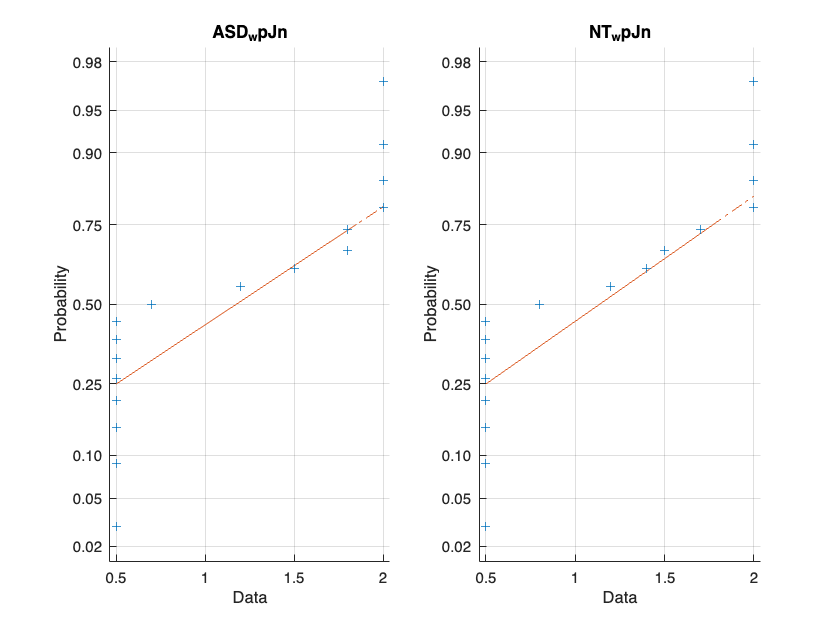

figure;
subplot(1,2,1)
normplot(ASD_wpJn)
title('ASD wpJn')
subplot(1,2,2)
normplot(NT_wpJn)
title('NT wpJn')

wpJn_diff = mwwtest(ASD_wpJn', NT_wpJn');

MANN-WHITNEY-WILCOXON TEST
 
                       Group_1    Group_2
                       _______    _______

    Numerosity             17         17 
    Sum_of_Rank_W         300        295 
    Mean_Rank          17.647     17.353 
    Test_variable_U       142        147 

Sample size is large enough to use the normal distribution approximation
 
    Mean       SD         Z        p_value_one_tail    p_value_two_tails
    _____    ______    ________    ________________    _________________

    144.5    27.279    0.073317        0.47078              0.94155     

 
